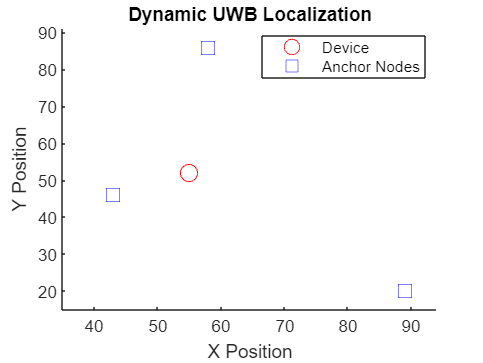

% Define initial positions for device and anchor nodes
deviceLocInitial = [50 50];  % Initial device position
nodeLocInitial = [40 41;     % Initial anchor node positions
                  62 83;
                  87 24];

% Define velocities for device and anchor nodes (change as needed)
deviceVelocity = [0.5, 0.2];   % Velocity of the device in x and y directions
nodeVelocities = [0.3, 0.5;    % Velocities of anchor nodes in x and y directions
                  -0.4, 0.3;
                  0.2, -0.4];

% Simulation parameters
numTimeSteps = 100;  % Number of time steps for simulation
timeStep = 0.1;      % Time step duration (adjust as needed)

% Initialize device and anchor node positions
deviceLoc = deviceLocInitial;
nodeLoc = nodeLocInitial;

% Initialize plot variables
figure;
hold on;
xlabel('X Position');
ylabel('Y Position');
title('Dynamic UWB Localization');
axis tight;

% Initialize plot limits
minX = min([deviceLocInitial(1), nodeLocInitial(:, 1)']);
maxX = max([deviceLocInitial(1), nodeLocInitial(:, 1)']);
minY = min([deviceLocInitial(2), nodeLocInitial(:, 2)']);
maxY = max([deviceLocInitial(2), nodeLocInitial(:, 2)']);
margin = 5; % Margin for zooming
axis([minX-margin maxX+margin minY-margin maxY+margin]);

% Plot initial positions of device and anchor nodes
devicePlot = plot(deviceLocInitial(1), deviceLocInitial(2), 'ro', 'MarkerSize', 10, 'DisplayName', 'Device');
nodePlot = plot(nodeLocInitial(:, 1), nodeLocInitial(:, 2), 'bs', 'MarkerSize', 10, 'DisplayName', 'Anchor Nodes');

% Main simulation loop
for t = 1:numTimeSteps
    % Update device position
    deviceLoc = deviceLoc + deviceVelocity * timeStep;
    
    % Update anchor node positions
    nodeLoc = nodeLoc + nodeVelocities * timeStep;
    
    % Update plot positions
    set(devicePlot, 'XData', deviceLoc(1), 'YData', deviceLoc(2));
    set(nodePlot, 'XData', nodeLoc(:, 1), 'YData', nodeLoc(:, 2));
    
    % Update plot limits dynamically to focus on changing positions
    minX = min([minX, deviceLoc(1), nodeLoc(:, 1)']);
    maxX = max([maxX, deviceLoc(1), nodeLoc(:, 1)']);
    minY = min([minY, deviceLoc(2), nodeLoc(:, 2)']);
    maxY = max([maxY, deviceLoc(2), nodeLoc(:, 2)']);
    axis([minX-margin maxX+margin minY-margin maxY+margin]);
    
    % Draw plot
    drawnow;

    % Run the localization algorithm with updated positions
    % Example code provided in the original question can be inserted here
    % You would need to integrate the localization algorithm using the dynamic positions of the device and anchor nodes
end

% Add legend
legend('Location', 'best');